# **IO3xx Interrupt v2 - Input Triggering **

This example demonstrates the use of an Interrupt Input pin to trigger a part of the model. You can test the basic functionality of IO3xx Interrupts by running this example.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1 x Interrupt channel** and **1x DIO channel**

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, a Digital Output is connected to the Interrupt Input. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Interrupt_v2_InputTriggering';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

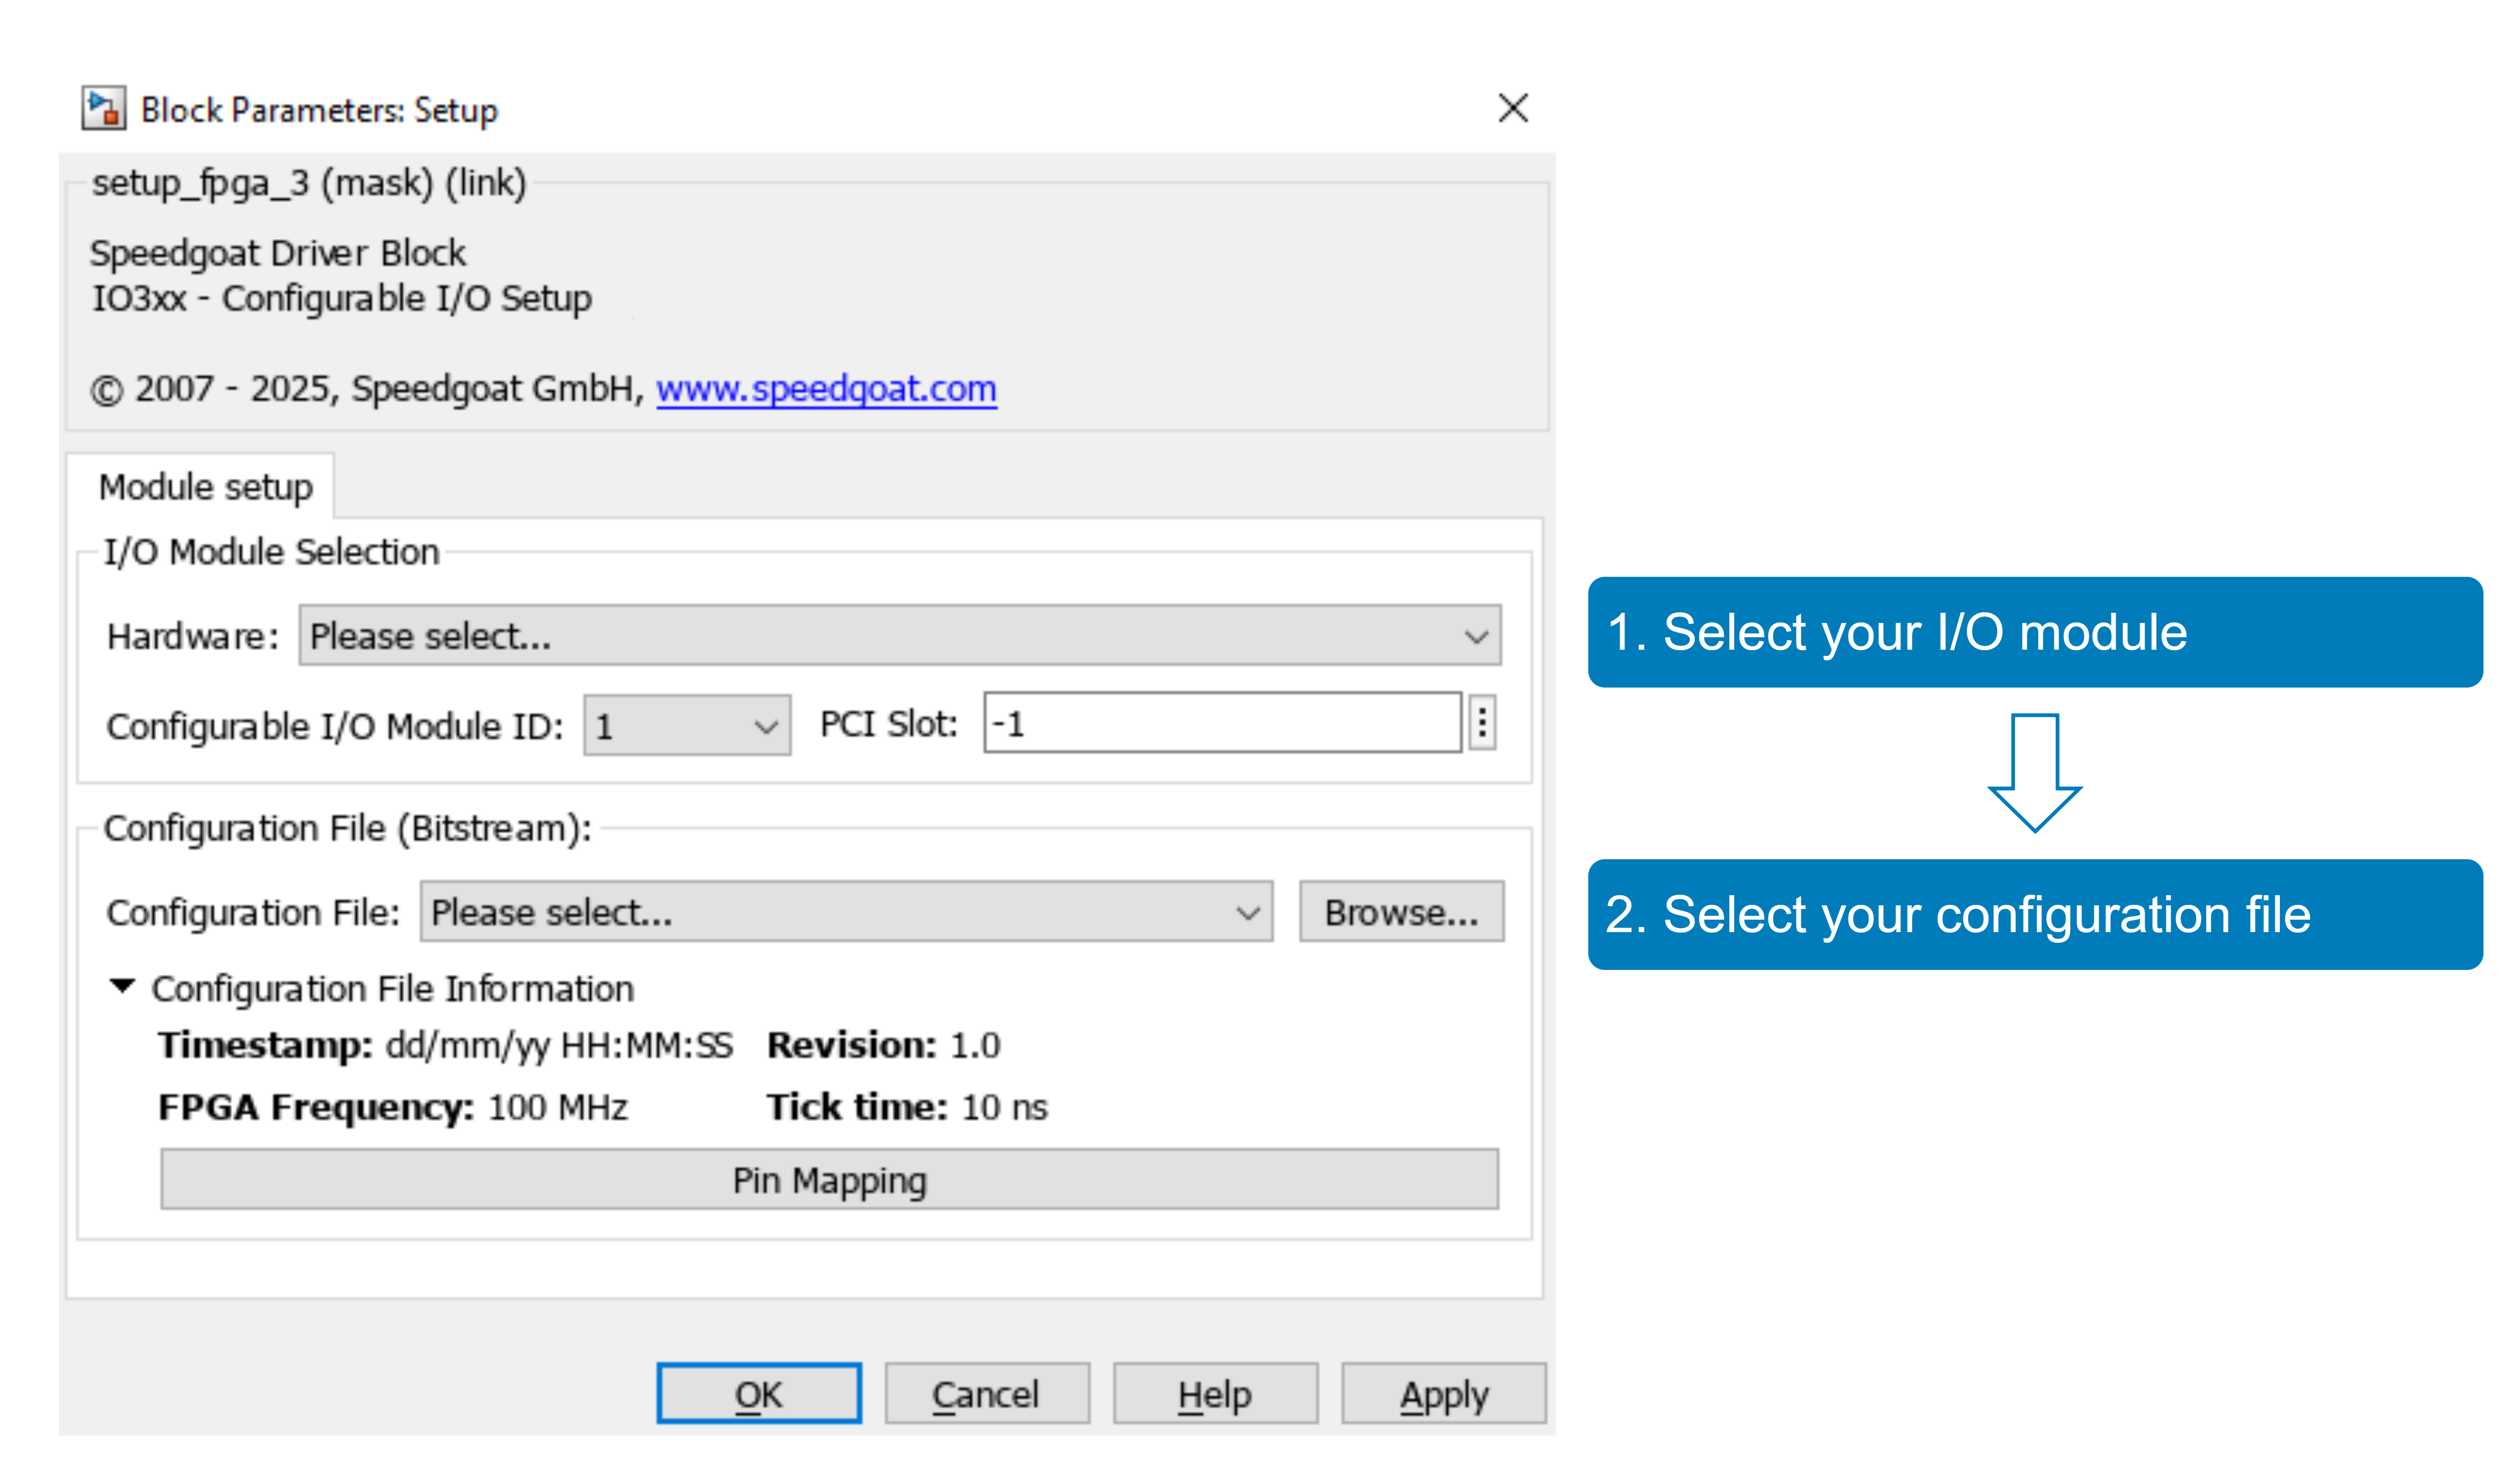

With the **Pin Mapping** button you can now check where the functionalities are located.

After setting up the I/O module, double click the Speedgoat Interrupt Setup block. Push the "Select Interrupt" button. In the newly opened window select the interrupt in the drop down.

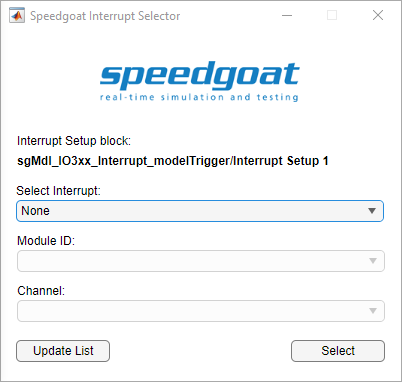

### Model Description

In the model, the Digital Output channel 1 is generating a 100Hz signal which triggers the Interrupt. In this example, the interrupt is configured to detect rising edges, which willl execute the [Function-call Subsystem](https://mathworks.com/help/simulink/slref/functioncallsubsystem.html) as an asynchronous task. An incrementing counter displays the number of received interrupts on the scope.  

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope that is connected to the interrupt counter. The scope must display the counter signal:

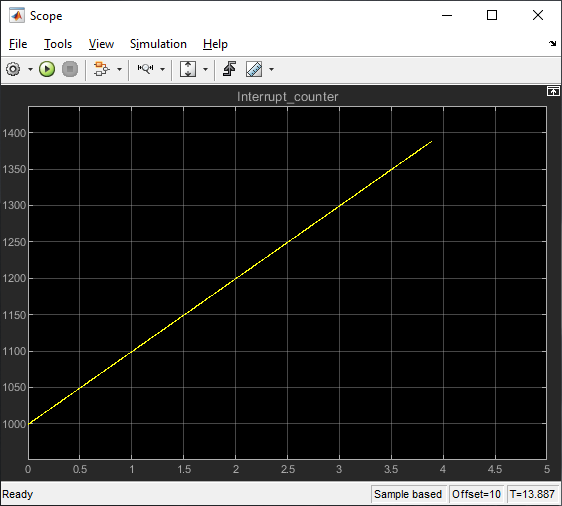

## Additional References

- [Interrupt documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt)